gunzip('https://github.com/sp-au-mu-nl/SpeechComm/raw/refs/heads/main/data/chap04.zip','data')

unzip('data/chap04.zip', 'data/chap04/')

プログラム 4.2

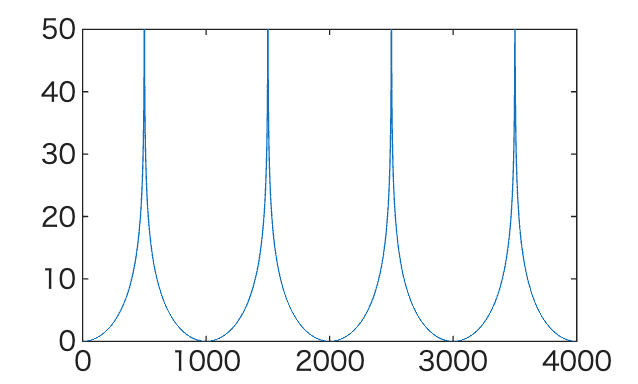

c = 340; lengthV = 0.17; fs = 8000;
frequency = 0:fs/2;
plot(frequency, 20*log10(abs(1./cos(2*pi*frequency*lengthV/c))));
ylim([0 50])

プログラム 4.3

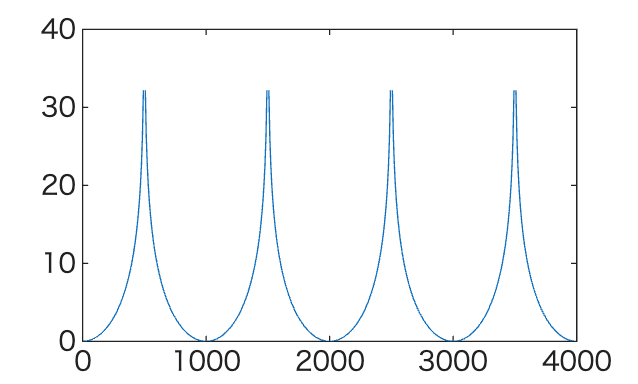

sr = 8000;
b(5) = 2;
a(1) = 1; a(9) = 1;
[H, w] = freqz(b, a);
f = sr*w/(2*pi);
plot(f, 20*log10(abs(H)))

プログラム 4.9 (章末問題 3)

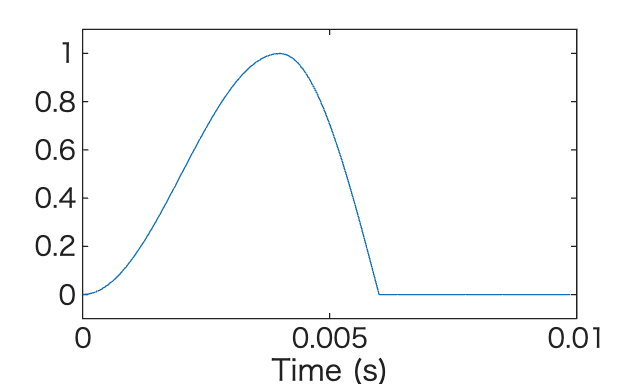

sr = 8000;
T1 = 0.004; T2 = 0.002;
t1 = 0:1/sr:T1-1/sr;
g1 = 0.5*(1-cos(2*pi*t1/2/T1));
t2 = T1:1/sr:T1+T2-1/sr;
g2 = cos(2*pi*(t2-T1)/4/T2);
t3 = T1+T2:1/sr:0.01-1/sr;
g3 = zeros(size(t3));
g = [g1 g2 g3]; % Combine the generated waveforms
t = [t1 t2 t3]; % Create a time vector for the combined signal
plot(t, g); % Plot the combined waveform
xlim([0 0.01]);
ylim([-.1 1.1])
xlabel('Time (s)');

プログラム 4.4

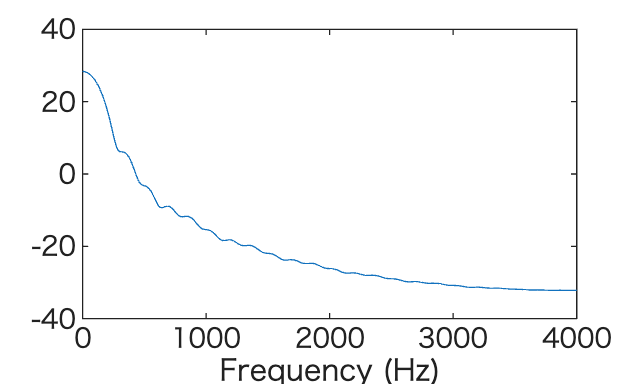

nFFT = 1024;
G = fft(g, nFFT);
frequency = linspace(0,sr/2,nFFT/2+1);
plot(frequency, 20*log10(abs(G(1:nFFT/2+1))))
xlabel('Frequency (Hz)')

プログラム 4.5

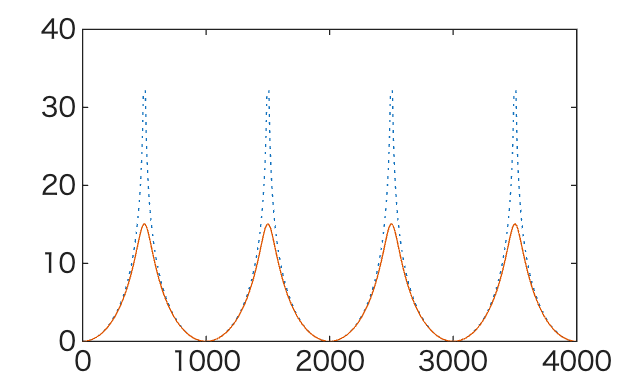

nFFT = 1024;
b(5) = 2;
a([1 9]) = 1;
[H, w] = freqz(b, a);
f = sr*w/(2*pi);
plot(f, 20*log10(abs(H)), ':'); hold on

rG = 0.7; rL = 1;
bLoss(5) = 0.5*(1+rG)*(1+rL);
aLoss(1) = 1; aLoss(9) = rL*rG;
[HLoss, ~] = freqz(bLoss, aLoss);
plot(f, 20*log10(abs(HLoss))); hold off

プログラム 4.6

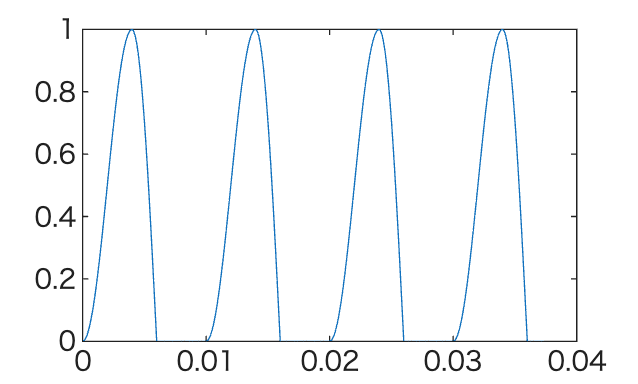

sr = 8000;
duration = 0.01;
nImpulse = int16(round(duration*sr));
impulse = zeros(1, nImpulse); impulse(1) = 1;
xImpulse = repmat(impulse, [1, int16(1/duration)]);
t = (0:length(xImpulse)-1)/sr;
r = 1:300;
soundsc(xImpulse, sr);
pause(length(xImpulse)/sr+1);

yGlottal = filter(g, 1, xImpulse);
plot(t(r), yGlottal(r));

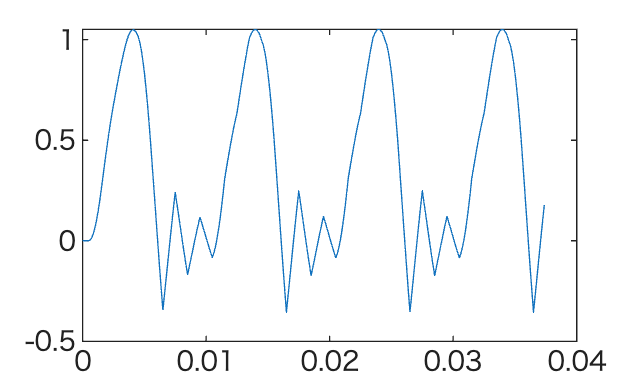

soundsc(yGlottal, sr);
pause(length(yGlottal)/sr+1);

yVowel = filter(bLoss, aLoss, yGlottal);
plot(t(r), yVowel(r))

soundsc(yVowel, sr)

プログラム 4.7

sr = 8000;

rG = 1; rL = 0.7;
a1a2 = 1/7; L1L2 = 1;
r1 = (1-a1a2)/(1+a1a2);

aA(1) = 1; aA(5) = r1*(rG+rL); aA(9) = rL*rG;
formant = angle(roots(aA))/2/pi*sr;
sort(formant(formant>0))

ans = 1.0e+03 *

    0.7758
    1.2242
    2.7758
    3.2242


プログラム 4.8

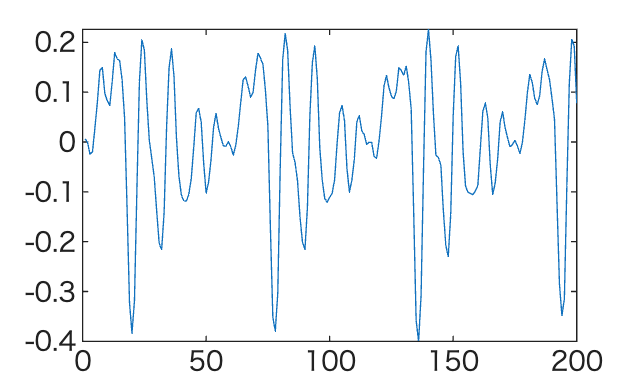

[ySa, sr] = audioread('data/chap04/sa48k.wav');
ySa = resample(ySa, 8000, sr);
sr = 8000;

plot(ySa(3200+(1:200)));

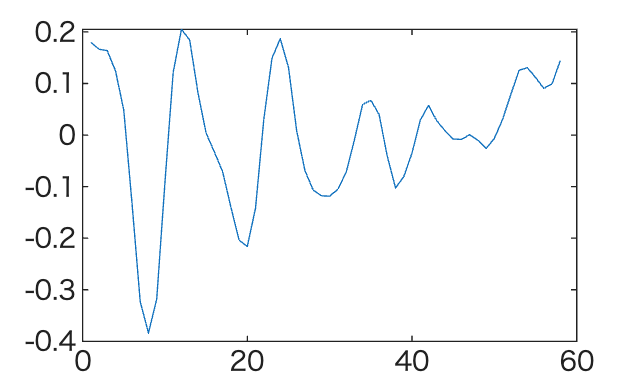

segment = ySa(3200+(13:70));
plot(segment)

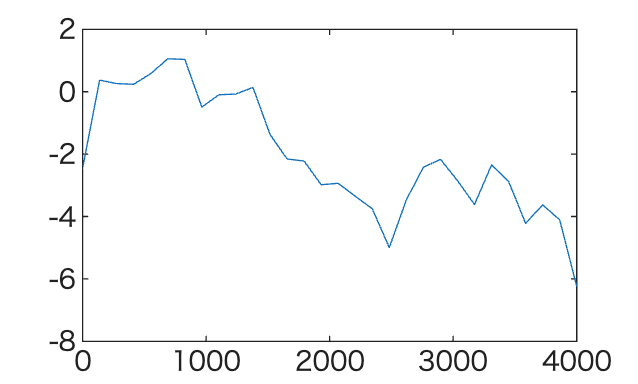

SA = fft(segment);
frequency = linspace(0,sr/2,floor(length(segment)/2)+1);
plot(frequency, log(abs(SA(1:floor(length(segment)/2)+1))))

プログラム 4.10

rG = 1; rL =0.7;
a1a2 = 27/73; L1L2 = 7/9;
L = 0.17; c = 340;
r1 = (1-a1a2)/(1+a1a2);
f = 0:(fs/2);
Va = freqz_two_tube(f, rL, rG, r1, L, c, L1L2);

SGlottal = fft(yGlottal);
SA = SGlottal(1:4001).*Va;
SA = [SA flip(conj(SA(2:end-1)))];
yA = ifft(SA);
soundsc(real(yA), fs)

function H = freqz_two_tube(f, rL, rG, r1, L, c, L1L2)
H = 0.5*(1+rG)*(1+rL)*(1+r1)*exp(-2j*pi*f*L/c)./ ...
    (1+r1*rG*exp(-2j*pi*f*2*L1L2/(L1L2+1)*L/c)+ ...
    r1*rL*exp(-2j*pi*f*2/(1+L1L2)*L/c)+ ...
    rL*rG*exp(-2j*pi*f*2*L/c));
end